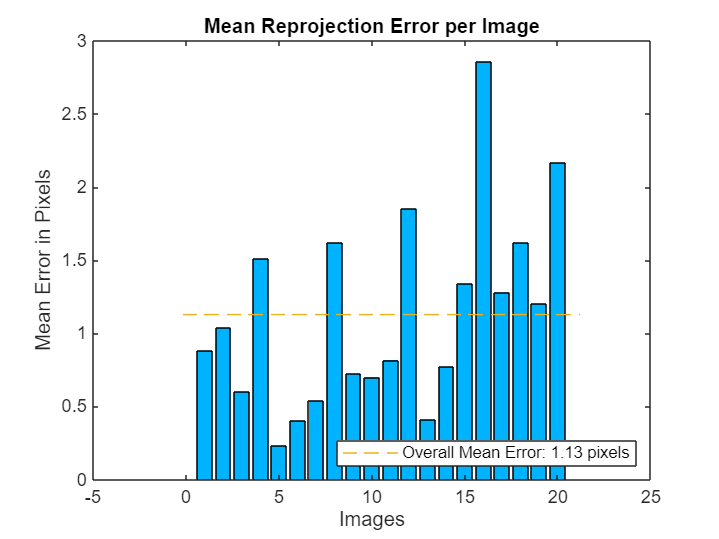

% Auto-generated by cameraCalibrator app on 16-Aug-2025
%-------------------------------------------------------


% Define images to process
imageFileNames = {'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal0_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal1_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal2_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal3_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal4_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal5_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal6_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal7_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal8_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal9_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal10_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal11_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal12_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal13_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal14_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal15_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal16_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal17_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal18_seg.png',...
    'C:\Users\GMADRO04\InternxtDrive - 9b57733c-7089-4577-8a63-3bde573d87c2\Maestría\PRIMER SEMESTRE\VISION POR COMPUTADOR\VisionsystemProject\fotos_cam_segmentadas\cal19_seg.png',...
    };
% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
minCornerMetric = 0.150000;
[imagePoints, imagesUsed] = detectPatternPoints(detector, imageFileNames, 'MinCornerMetric', minCornerMetric);
imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread('fotos_1280_1080/cal0.png');
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25.000000;  % in millimeters
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

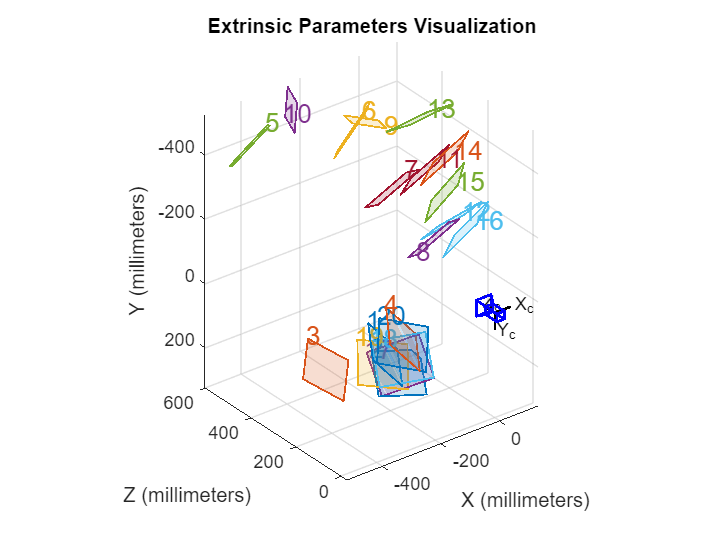


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  179.6641 +/- 3.0599      182.4534 +/- 3.1956  ]
Principal point (pixels):[  614.5876 +/- 1.0096      574.8432 +/- 0.4639  ]
Radial distortion:       [   -0.2679 +/- 0.0094        0.0430 +/- 0.0034  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.8593 +/- 0.0421       -0.3777 +/- 0.0381        0.8067 +/- 0.0172  ]
                         [   -0.6875 +/- 0.0349        0.0813 +/- 0.0307        0.2723 +/- 0.0154  ]
                         [   -0.7177 +/- 0.0417       -0.0309 +/- 0.0392        0.7333 +/- 0.0192  ]
                         [   -0.8473 +/- 0.0272       -0.3629 +/- 0.0254        0.8125 +/- 0.0114  ]
                         [   -0.2271 +/- 0.1663       -1.0207 +/- 0.1955        2.2594 +/- 0.0736  ]
                         [   -0.4678 +/- 0.0727       -0.8351 +/- 0.0813        2.4282 +/- 0.0420  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')

% Guardar parametrod para usarlos en matlab y en yml para python
%% ==== Guardar cameraParams en .mat y .yml ====
outDir = 'calib_output';                          % carpeta de salida
if ~exist(outDir,'dir'), mkdir(outDir); end

H = cameraParams.ImageSize(1);
W = cameraParams.ImageSize(2);
meanErr = mean(cameraParams.MeanReprojectionError);

% 1) .MAT (nombra por resolución)
matPath = fullfile(outDir, sprintf('cameraParams_%dx%d.mat', W, H));
save(matPath, 'cameraParams');
fprintf('>> Guardado MAT: %s\n', matPath);

>> Guardado MAT: calib_output\cameraParams_1280x1080.mat



% 2) .YML (intrínseca + distorsión + metadatos)
ymlPath = fullfile(outDir, sprintf('cameraParams_%dx%d.yml', W, H));
escribir_camparams_yaml(ymlPath, cameraParams, meanErr, 'millimeters');
fprintf('>> Guardado YAML: %s\n', ymlPath);

>> Guardado YAML: calib_output\cameraParams_1280x1080.yml


function escribir_camparams_yaml(ymlPath, cameraParams, meanErr, worldUnits)
% Escribe un YAML compacto con intrínseca, distorsión, tamaño e info básica.

    if nargin < 4 || isempty(worldUnits), worldUnits = 'pixels'; end
    K = cameraParams.IntrinsicMatrix';           % K "normal"
    fx = K(1,1);  fy = K(2,2);
    cx = K(1,3);  cy = K(2,3);
    H  = cameraParams.ImageSize(1);
    W  = cameraParams.ImageSize(2);
    skew = 0.0;                                   % cameraParameters no expone skew

    k = cameraParams.RadialDistortion;           % k1 k2 (k3 si existe)
    k = k(:)';                                   % fila
    if numel(k) == 2, k = [k 0]; end            % normaliza a 3 para consistencia
    if isprop(cameraParams,'TangentialDistortion')
        p = cameraParams.TangentialDistortion;
    else
        p = [0 0];
    end
    p = p(:)'; if isempty(p), p = [0 0]; end

    f = fopen(ymlPath,'w');
    assert(f>0, 'No se pudo abrir %s para escritura.', ymlPath);
    c = onCleanup(@() fclose(f));

    fprintf(f, 'camera:\n');
    fprintf(f, '  imageSize: [%d, %d]\n', H, W);
    fprintf(f, '  worldUnits: "%s"\n', worldUnits);
    fprintf(f, '  focalLength: [%.10f, %.10f]\n', fx, fy);
    fprintf(f, '  principalPoint: [%.10f, %.10f]\n', cx, cy);
    fprintf(f, '  skew: %.10f\n', skew);
    fprintf(f, '  intrinsicMatrix:\n');
    fprintf(f, '    - [%.10f, %.10f, %.10f]\n', fx, 0.0, cx);
    fprintf(f, '    - [%.10f, %.10f, %.10f]\n', 0.0, fy, cy);
    fprintf(f, '    - [%.10f, %.10f, %.10f]\n', 0.0, 0.0, 1.0);
    fprintf(f, '  distortionModel: "brown-conrady"\n');
    fprintf(f, '  radialDistortion: [%.12f, %.12f, %.12f]\n', k(1), k(2), k(3));
    fprintf(f, '  tangentialDistortion: [%.12f, %.12f]\n', p(1), p(2));
    fprintf(f, '  reprojectionErrorPx: %.6f\n', meanErr);
    fprintf(f, '  timestamp: "%s"\n', datestr(datetime('now'), 'yyyy-mm-ddTHH:MM:SS'));
    fprintf(f, '  source: "MATLAB cameraCalibrator"\n');
end